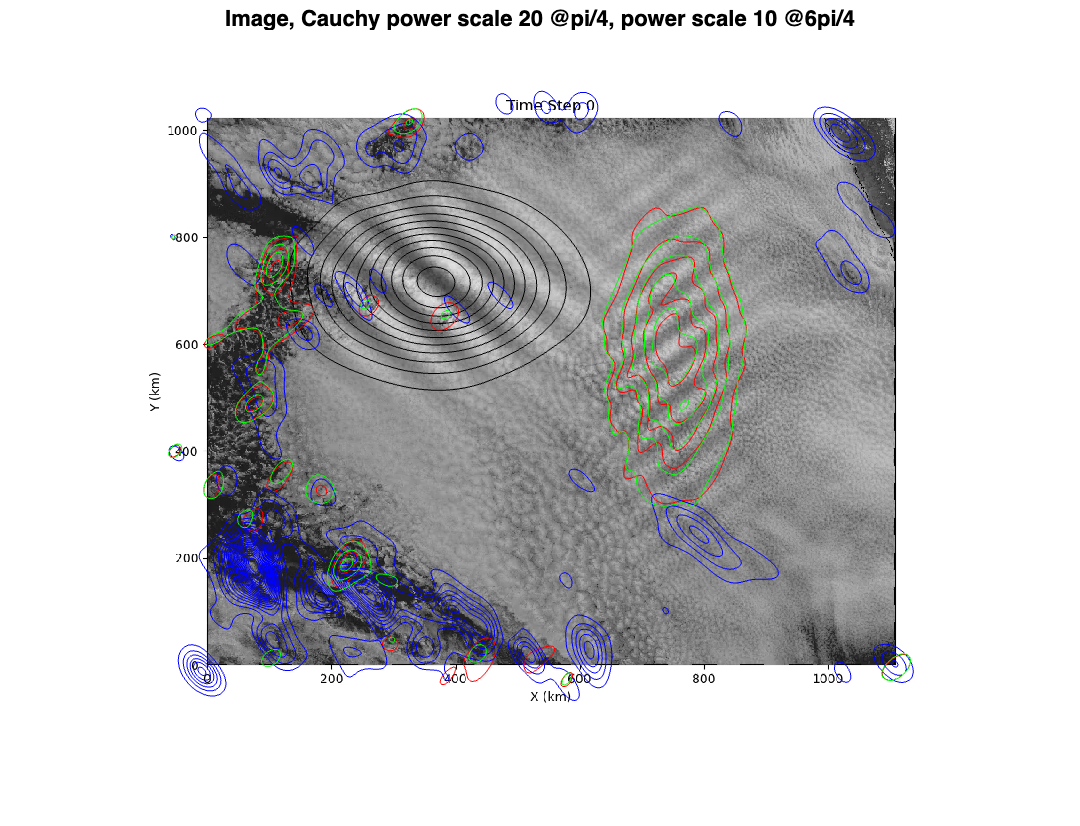

% Path sucks: Drag mp4 into workspace and set img to frames  

img = syn_scwave_warp_modx5(:,:,1,1);

% 16 angles 
angz = {"0", "pi/8", "pi/4", "3pi/8", "pi/2", "5pi/8", "3pi/4", ...
    "7pi/8","pi", "9pi/8", "5pi/4", "11pi/8", "3pi/2", ...
    "13pi/8" "7pi/4", "15pi/8"};

% Couple of scales
cwtScales = [10,20];


cwtCauchy = cwtft2(img,wavelet="cauchy",scales=cwtScales, angles=cwtAngles);

% RESULT: size 800, 1000, 1?, 2 SCALES, 16 ANGLES


% Wavelet power on image 
imshow(img)
title('Image, Cauchy power scale 20 @pi/4, power scale 10 @6pi/4')
hold on
% Real part is crests and trofs, imag is gradients, abs is a magnitude map 
% contour(real(cwtCauchy.cfs(:,:,1,1,3)))

% SCALE 20, ANGLE 3 (pi/4)
contour(abs(cwtCauchy.cfs(:,:,1,2,3).^2), color='k')

% SCALE 10, ANGLE 7, red
contour(abs(cwtCauchy.cfs(:,:,1,1,7).^2), color='r')

% SCALE 10, ANGLE 3, blue: CATCHES SOME NATIVE WAVES IN SE! 
% But also sharp edge in SW area. 
% IDEA: filter for modest amplitudes to throw out artificial edges! 
contour(abs(cwtCauchy.cfs(:,:,1,1,3).^2), 20, color='b')





%%%%%%
% Cross wavelet: second frame and its complex spectrum 
img2 = syn_scwave_warp_modx5(:,:,1,2);
cwtCauchy2 = cwtft2(img2,wavelet="cauchy",scales=cwtScales, angles=cwtAngles);

% Plot cross-coherence, is it clearer than power at one time? 
xwavelet = cwtCauchy.cfs .* conj(cwtCauchy2.cfs);

% SCALE 10, ANGLE 7, green, scale 10, angle 7
contour(abs(xwavelet(:,:,1,1,7)), color='g')
hold off

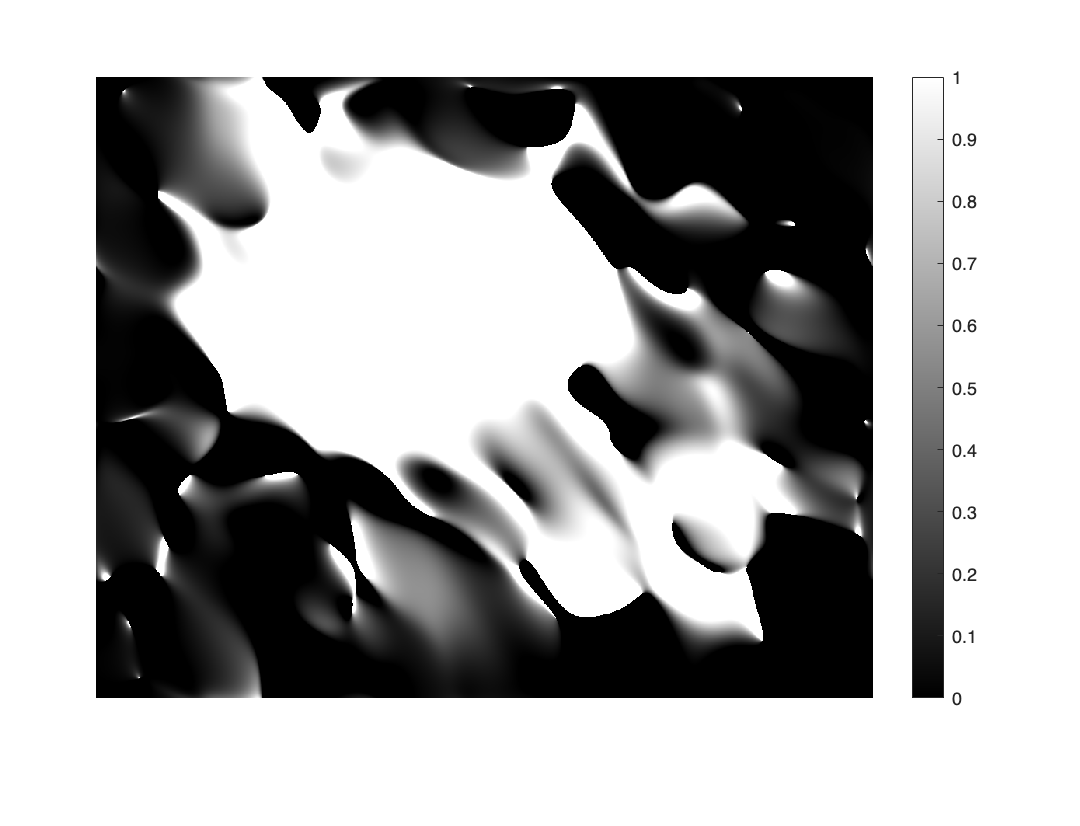


% Phase angle: for northwest (scale 20, angle 3)
% values should say how many radians this component
% has propagated in the time interval between frames,
% to be converted to a phase speed. Weirdly, in [0,1]!
% More tinkering needed 

imshow( angle(xwavelet(:,:,1,2,3)) ); colorbar; 